load("test_functions2.mat", '-mat')

# Function one

disp_int = [-20 20]

disp_int =    -20    20


x_start = [18 18]'

x_start =     18
    18


[xk,fk,gradfk_norm,k,xseq] = newton(x_start,f1,gradf1,Hessf1,kmax,tolgrad);


## Contour plot

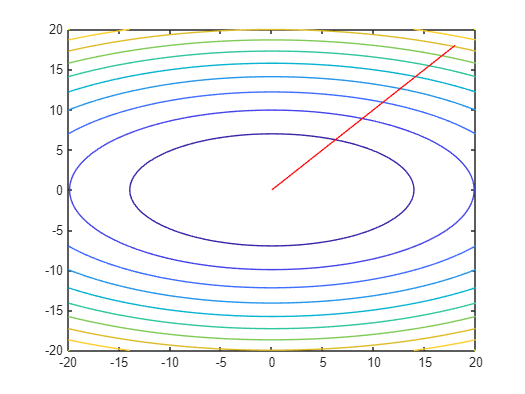

f1_meshgrid = @(X,Y)reshape(f1([X(:),Y(:)]'),size(X));
fcontour(f1_meshgrid,disp_int);
hold on
h = plot(xseq(1,:), xseq(2,:), '-r', 'linewidth', 1, 'markersize', 5);
hold off

## Surface plot

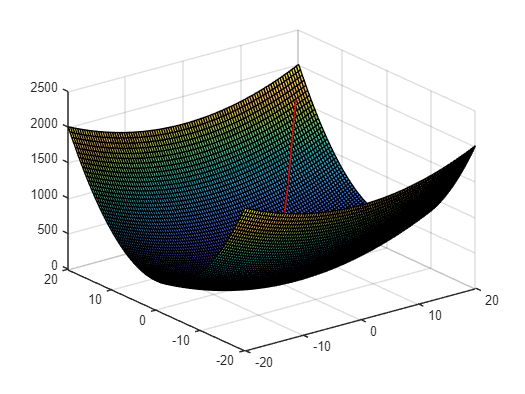

x = linspace(disp_int(1), disp_int(2));
[X,Y] = meshgrid(x,x);
f1_surf = f1_meshgrid(X,Y);

surf(X,Y,f1_surf)
hold on 
view(3)
plot3(xseq(1,:), xseq(2,:), f1_meshgrid(xseq(1,:), xseq(2,:)), "-r")
hold off

# Function 2

## Contour plot

disp_int = [-50 50]

disp_int =    -50    50


x_start = x0

x_start =     -5
    -5


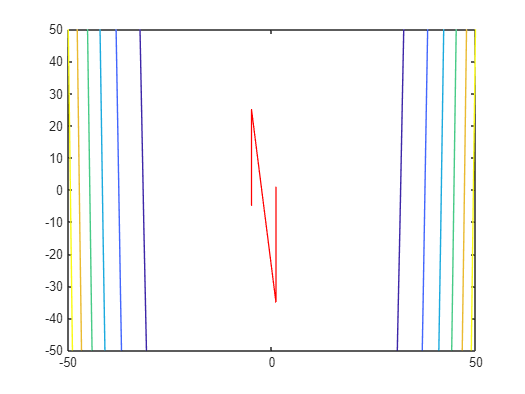

[xk,fk,gradfk_norm,k,xseq] = newton(x_start,f2,gradf2,Hessf2,kmax,tolgrad);

f2_meshgrid = @(X,Y) reshape(f2([X(:),Y(:)]'),size(X));
fcontour(f2_meshgrid, disp_int);
hold on
h = plot(xseq(1,:), xseq(2,:), '-r', 'linewidth', 1, 'markersize', 5);
hold off

## Surface plot

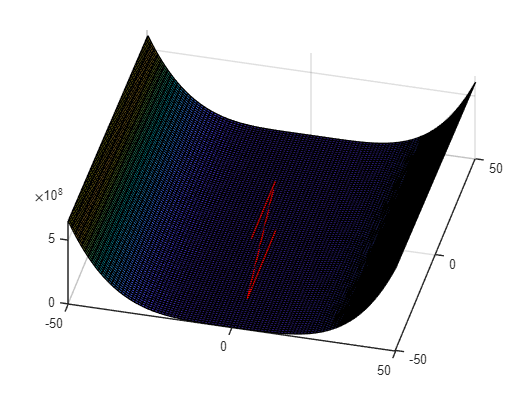

x = linspace(-50,50);
y = linspace(-50,50);
[X,Y] = meshgrid(x,y);
f2_surf = f2_meshgrid(X,Y);


surf(X,Y,f2_surf)
hold on 
view(3)
plot3(xseq(1,:), xseq(2,:), f2_meshgrid(xseq(1,:), xseq(2,:)), "-r")
hold off

# Function 3

%% Funciton 3
disp_int = [-20 20]

disp_int =    -20    20


x_start = [18 18]'

x_start =     18
    18


[xk,fk,gradfk_norm,k,xseq] = newton(x_start,f3,gradf3,Hessf3,kmax,tolgrad);

#### Contour plot

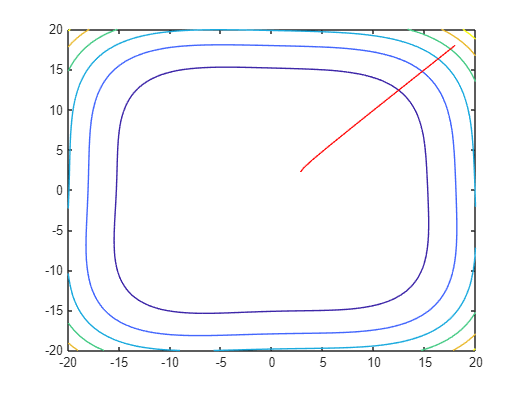

% contour
f3_meshgrid = @(X,Y) reshape(f3([X(:),Y(:)]'), size(X));
fcontour(f3_meshgrid,disp_int);
hold on
h = plot(xseq(1,:), xseq(2,:), '-r', 'linewidth', 1, 'markersize', 5);
hold off

## Surface plot

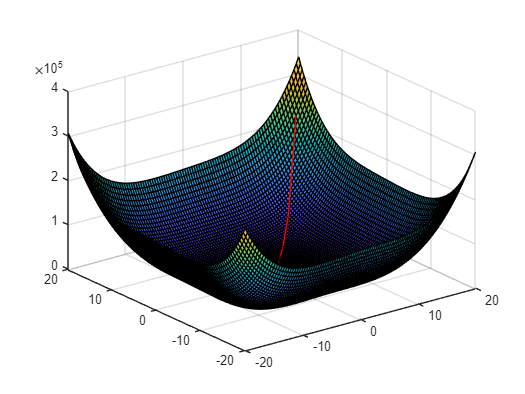

x = linspace(disp_int(1), disp_int(2));
[X,Y] = meshgrid(x,x);
f3_surf = f3_meshgrid(X,Y);

surf(X,Y,f3_surf)
hold on 
view(3)
plot3(xseq(1,:), xseq(2,:), f3_meshgrid(xseq(1,:), xseq(2,:)), "-r")
hold off